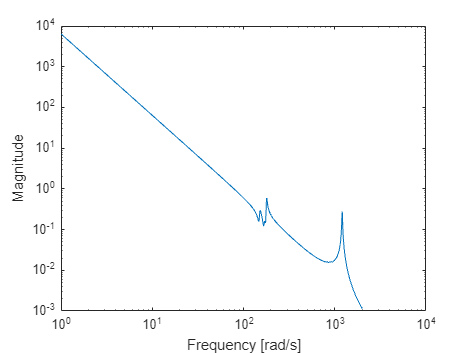

clear;
load("waferstage.mat")

bodeplm(hz',frf')

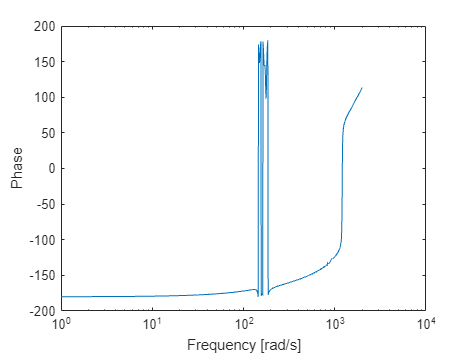

bodeplp(hz',frf')


[num, den] = frsfit(frf,hz,[2+2+2, 0+2+1, 2],1)

initial estimate of FRQLS
determination of initial errors
 
Building original data matrix
 
Start output error iterations
OE iteration 1; a/m-re of 1/den: 1 211.0571
OE iteration 2; a/m-re of 1/den: 0.99053 0.99332
OE iteration 3; a/m-re of 1/den: 0.54288 0.9421
OE iteration 4; a/m-re of 1/den: 0.38363 1.963
OE iteration 5; a/m-re of 1/den: 0.14538 2.029
OE iteration 6; a/m-re of 1/den: 0.040679 0.93261
OE iteration 7; a/m-re of 1/den: 0.0124 0.49979
OE iteration 8; a/m-re of 1/den: 0.0046428 0.26563
OE iteration 9; a/m-re of 1/den: 0.0022031 0.11591
OE iteration 10; a/m-re of 1/den: 0.0010066 0.06588
OE iteration 11; a/m-re of 1/den: 0.00055719 0.029162
OE iteration 12; a/m-re of 1/den: 0.0002593 0.017859
OE iteration 13; a/m-re of 1/den: 0.00015297 0.0081048
OE iteration 14; a/m-re of 1/den: 6.8188e-05 0.0049153
OE iteration 15; a/m-re of 1/den: 4.3401e-05 0.0022355
OE iteration 16; a/m-re of 1/den: 1.7486e-05 0.0013459
OE iteration 17; a/m-re of 1/den: 1.2766e-05 0.00061489
OE itera

num =             0            0            0  -1.5567e+09   1.2403e+13  -1.2463e+15   1.0798e+19


den =    1.0000e+00   1.3937e+02   5.7758e+07   1.0199e+09   4.9789e+13            0            0


figure()
H = tf(num,den)

H =
 
      -1.557e09 s^3 + 1.24e13 s^2 - 1.246e15 s + 1.08e19
  -----------------------------------------------------------
  s^6 + 139.4 s^5 + 5.776e07 s^4 + 1.02e09 s^3 + 4.979e13 s^2
 
Continuous-time transfer function.
Model Properties


pole(H)

ans =    0.0000e+00 + 0.0000e+00i
   0.0000e+00 + 0.0000e+00i
  -6.1668e+01 + 7.5417e+03i
  -6.1668e+01 - 7.5417e+03i
  -8.0162e+00 + 9.3555e+02i
  -8.0162e+00 - 9.3555e+02i


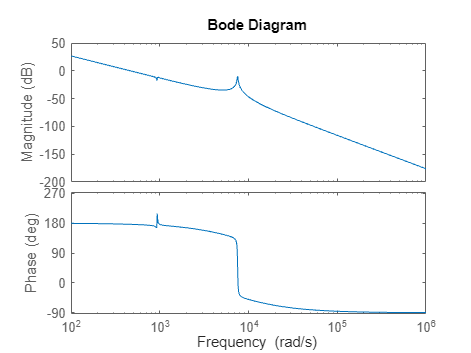

bode(H)